Breakdown of the points:

- **0.25p**   – an established communication channel and appropriate strategy for code sharing.

- **0.25p**   – data correctly imported into appropriate matrices completely: observations as rows, variables (predictors) as columns.

- **0.5p**     – identification of challenges of the data: for example: time series not synchronized, missing values in data, extra variables, variables with unknown physical meanings, etc.

- **0.5p**     – a visualization and comment on the dataset: variable distribution, number of observations, type of measurements (time series or not time series)

- **3p **        -  exploratory data analysis with PCA: explain variable correlations and visualize the PCs using biplots, loading plots; (! only on the X matrix - we are not looking at the response variable now)

- **0.5p**     – identification of pretreatment steps, and a plan on how to do data pretreatment

data correctly imported into appropriate matrices completely: observations as rows, variables (predictors) as columns.

clc;clear;

data = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data.Properties.VariableNames{1} = 'SampleID';

data_numbers = length(data.SampleID)

data_numbers = 12180


trait_names = data.Properties.VariableNames(2:21);
trait_numbers = 20;
wave_lengths = str2double(data.Properties.VariableNames(22:end));
wave_numbers = 1721;


identification of challenges of the data: for example: time series not synchronized, missing values in data, extra variables, variables with unknown physical meanings, etc.

a visualization and comment on the dataset: variable distribution, number of observations, type of measurements (time series or not time series)

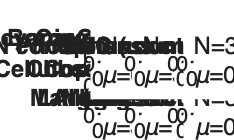

% variable distribution

figure;
clf;
tiledlayout(4,5);

% trait
for j = 1:trait_numbers
    tmp_x = table2array(data(:,trait_names(j)));
    % remove NaN
    tmp_x = tmp_x(~isnan(tmp_x));              
    nexttile;
    
    histogram(tmp_x, 'Normalization','probability', 'BinMethod','fd', 'EdgeColor','none');
    ylabel('Probability');

    xlabel('Value');
    title(string(trait_names(j)));

    % simple statistics
    valid_numbers = numel(tmp_x);
    missRate = 1 - valid_numbers / data_numbers;
    tmp_x_mean = mean(tmp_x);
    tmp_x_std  = std(tmp_x);

    xl = xlim; 
    yl = ylim;
    note = sprintf('N=%d  miss=%.1f%%\n\\mu=%.3g  \\sigma=%.3g', ...
                   valid_numbers, missRate*100, tmp_x_mean, tmp_x_std);
    text(xl(1) + 0.02*range(xl), yl(2) - 0.10*range(yl), note, ...
        'FontSize', 9, 'BackgroundColor', [1 1 1 0.7], 'Margin', 3);
end

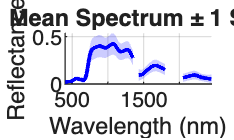

% NaN insert
spectra_data = table2array(data(:,22:end));
mean_spectra = mean(spectra_data, 1, 'omitnan');
std_spectra  = std(spectra_data, 0, 1, 'omitnan');

wl = wave_lengths;

d = diff(wl);
gapIdx = find(d > 1);

segStarts = [1, gapIdx+1];
segEnds   = [gapIdx, numel(wl)];

figure; clf; hold on;

for k = 1:numel(segStarts)
    idx = segStarts(k):segEnds(k);
    x  = wl(idx);
    mu = mean_spectra(idx);
    sd = std_spectra(idx);

    patch([x, fliplr(x)], [mu-sd, fliplr(mu+sd)], ...
          'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

    plot(x, mu, 'b', 'LineWidth', 1.5);
end

xlabel('Wavelength (nm)');
ylabel('Reflectance');
title('Mean Spectrum ± 1 Std');
xlim([400, 2450]);
grid on;


% spectra continuous
spectra_data = table2array(data(:,22:end))

spectra_data =     0.0126    0.0127    0.0128    0.0129    0.0130    0.0132    0.0133    0.0134    0.0135    0.0136    0.0137    0.0138    0.0140    0.0141    0.0142    0.0143    0.0144    0.0145    0.0146    0.0148    0.0149    0.0150    0.0151    0.0152    0.0153    0.0154    0.0156    0.0157    0.0158    0.0159    0.0160    0.0161    0.0162    0.0163    0.0164    0.0165    0.0166    0.0167    0.0168    0.0169    0.0170    0.0171    0.0172    0.0173    0.0174    0.0175    0.0175    0.0176    0.0177    0.0178
    0.0195    0.0196    0.0197    0.0198    0.0199    0.0200    0.0201    0.0202    0.0203    0.0204    0.0205    0.0206    0.0207    0.0208    0.0209    0.0210    0.0211    0.0212    0.0213    0.0214    0.0215    0.0216    0.0217    0.0218    0.0219    0.0220    0.0221    0.0223    0.0224    0.0225    0.0226    0.0227    0.0228    0.0228    0.0229    0.0230    0.0231    0.0232    0.0233    0.0234    0.0234    0.0235    0.0236    0.0237    0.0238    0.0238    0.0239    0.0240    

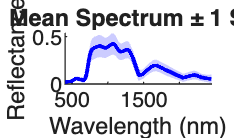

mean_spectra = mean(spectra_data, 1, 'omitnan');
std_spectra  = std(spectra_data, 0, 1, 'omitnan');

figure;
clf;
hold on;

% spectra mean and std plot
plot(wave_lengths, mean_spectra, 'b', 'LineWidth', 1.5);
fill([wave_lengths fliplr(wave_lengths)], ...
     [mean_spectra-std_spectra fliplr(mean_spectra+std_spectra)], ...
     'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
xlabel('Wavelength (nm)');
ylabel('Reflectance');
xlim([400, 2450]);
title('Mean Spectrum ± 1 Std');

exploratory data analysis with PCA: explain variable correlations and visualize the PCs using biplots, loading plots; (! only on the X matrix - we are not looking at the response variable now)

% normalize
spectra_data_normalized = (spectra_data - mean_spectra)./std_spectra;

% PCA
[coeff, score, latent, tsquared, explained] = pca(spectra_data_normalized, 'Algorithm','svd');

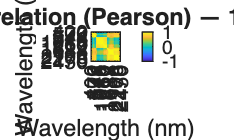


% correlation visualization

% sample if want to show less
selected_bands_numbers = wave_numbers;                             
if wave_numbers > selected_bands_numbers
    % sample
    idx = round(linspace(1, wave_numbers, selected_bands_numbers));
else
    idx = 1:wave_numbers;
end
spectra_data_normalized_s  = spectra_data_normalized(:, idx);
wave_lengths_s = wave_lengths(idx);

% correlation
corrType = 'Pearson';
R = corr(spectra_data_normalized_s, 'Type', corrType, 'Rows', 'pairwise');

% heatmap
figure; 
clf;
imagesc(wave_lengths_s, wave_lengths_s, R, [-1 1]); axis image; colormap(parula); colorbar;
xlabel('Wavelength (nm)'); ylabel('Wavelength (nm)');
title(sprintf('Spectral correlation (%s) — %d bands', corrType, numel(idx)));
set(gca,'XTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end), ...
        'YTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end));

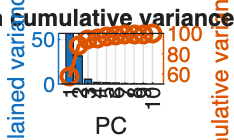

%% scree plot
figure(); 
clf;

yyaxis left
% first 10 principal component
bar(explained(1:10));                 
ylabel('Explained variance (%)');

yyaxis right
% cumulative variance
plot(cumsum(explained(1:10)), '-o', 'LineWidth',1.5);
ylabel('Cumulative variance (%)');

xlabel('PC');
title('Scree plot with cumulative variance (first 10 PCs)');
grid on;

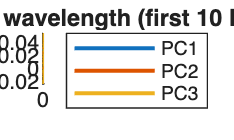

%% loading plots
figure();
clf; 
hold on;

% PC numbers wanted to show
numPC = 3;
colors = lines(numPC);

for k = 1:numPC
    plot(wave_lengths, coeff(:,k), 'LineWidth', 1.5, 'Color', colors(k,:));
end

xlabel('Wavelength (nm)'); 
ylabel('Loading');
legend("PC"+string(1:numPC), 'Location','bestoutside'); % 图例自动生成 PC1-PC10
title('Loading plots vs. wavelength (first 10 PCs)');
grid on;

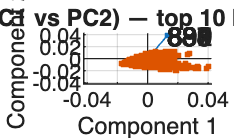

%% biplot conbine PC1 and PC2

% wavelength numbers wanted to show
K = 10;
% PC1-PC2 contributions
w = sqrt(coeff(:,1).^2 + coeff(:,2).^2); 
% first K
[~, idx] = maxk(w, K);                        
labels = string(round(wave_lengths(idx)));

figure(); 
clf;
biplot(coeff(idx,1:2), 'Scores', score(:,1:2), 'VarLabels', labels);
title(sprintf('Biplot (PC1 vs PC2) — top %d bands labelled', K));

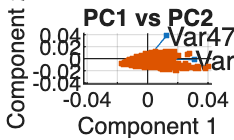

% biplot separately
numPCs = 2;
topVarIdx = zeros(1, numPCs);

for i = 1:numPCs
    [~, idx] = max(abs(coeff(:,i)));  % index of variable with largest loading
    topVarIdx(i) = idx;
end
for i = 1:2:numPCs
    figure;
    biplot(coeff(topVarIdx(i:i+1),i:i+1), 'Scores', score(:,i:i+1), 'VarLabels', ...
        arrayfun(@(x) ['Var' num2str(x)], topVarIdx(i:i+1), 'UniformOutput', false));
    title(['PC' num2str(i) ' vs PC' num2str(i+1)]);
end

identification of pretreatment steps, and a plan on how to do data pretreatment